ESCALÓN RL

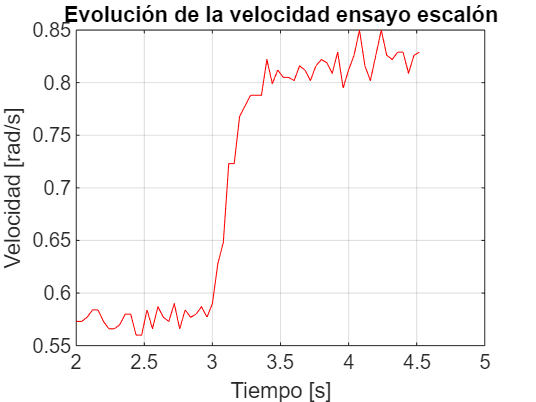

escalon=[
2.000 89 17.640 0.573
2.040 89 17.640 0.573
2.080 89 17.745 0.577
2.120 89 17.955 0.584
2.160 89 17.955 0.584
2.200 89 17.640 0.573
2.240 89 17.430 0.566
2.280 89 17.430 0.566
2.320 89 17.535 0.570
2.360 89 17.850 0.580
2.400 89 17.850 0.580
2.440 89 17.220 0.560
2.480 89 17.220 0.560
2.520 89 17.955 0.584
2.560 89 17.430 0.566
2.600 89 18.060 0.587
2.640 89 17.745 0.577
2.680 89 17.640 0.573
2.720 89 18.165 0.590
2.760 89 17.428 0.566
2.800 89 17.955 0.584
2.840 89 17.745 0.577
2.880 89 17.850 0.580
2.920 89 18.060 0.587
2.960 89 17.745 0.577
3.000 150 18.165 0.590
3.040 150 19.319 0.628
3.080 150 19.949 0.648
3.120 150 22.259 0.723
3.160 150 22.259 0.723
3.200 150 23.625 0.768
3.240 150 23.940 0.778
3.280 150 24.254 0.788
3.320 150 24.255 0.788
3.360 150 24.255 0.788
3.400 150 25.304 0.822
3.440 150 24.570 0.799
3.480 150 24.990 0.812
3.520 150 24.779 0.805
3.560 150 24.780 0.805
3.600 150 24.675 0.802
3.640 150 25.094 0.816
3.680 150 24.989 0.812
3.720 150 24.675 0.802
3.760 150 25.094 0.816
3.800 150 25.304 0.822
3.840 150 25.199 0.819
3.880 150 24.885 0.809
3.920 150 25.515 0.829
3.960 150 24.464 0.795
4.000 150 24.989 0.812
4.040 150 25.410 0.826
4.080 150 26.144 0.850
4.120 150 25.094 0.816
4.160 150 24.675 0.802
4.200 150 25.409 0.826
4.240 150 26.144 0.850
4.280 150 25.410 0.826
4.320 150 25.304 0.822
4.360 150 25.515 0.829
4.400 150 25.514 0.829
4.440 150 24.885 0.809
4.480 150 25.409 0.826
4.520 150 25.515 0.829
];

t = escalon(:,1);
refPWM = escalon(:,2);
u = refPWM - refPWM(1); %Entrada del System Identification
w    = escalon(:,3);
vel = escalon(:,4);
y = vel - vel(1); %Salida del System Identification

figure
plot(t, vel, 'r');
xlabel('Tiempo [s]');
ylabel('Velocidad [rad/s]');
title('Evolución de la velocidad ensayo escalón');
grid on;

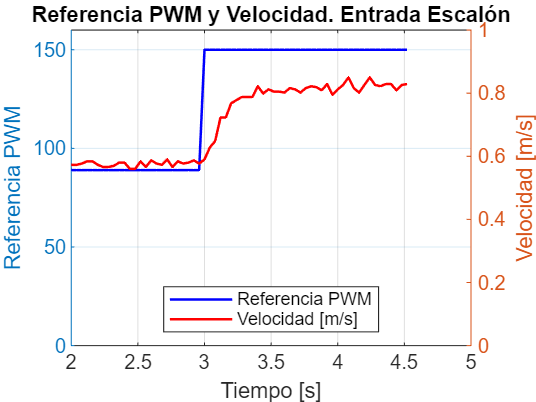


figure;
% Eje izquierdo (referencia PWM)
yyaxis left
p1 = plot(t, refPWM, 'b-', 'LineWidth', 1.2); hold on;
ylim([0 160]);                 % límites del eje izquierdo
ylabel('Referencia PWM');

% Eje derecho (velocidad)
yyaxis right
p2 = plot(t, vel, 'r-', 'LineWidth', 1.2); hold on;
ylim([0 1]);                    % límites del eje derecho
ylabel('Velocidad [m/s]');

xlabel('Tiempo [s]');
title('Referencia PWM y Velocidad. Entrada Escalón');
grid on;

legend({'Referencia PWM','Velocidad [m/s]'}, 'Location','south');

RESPUESTA AL ESCALÓN EN BUCLE ABIERTO

figure
G=tf(tf1) %cargamos nuestro modelo de System Identification


G =
 
  From input "u1" to output "y1":
     0.000738
  ---------------
  1 - 0.8205 z^-1
 
Name: tf1
Sample time: 0.04 seconds
Discrete-time transfer function.
Model Properties


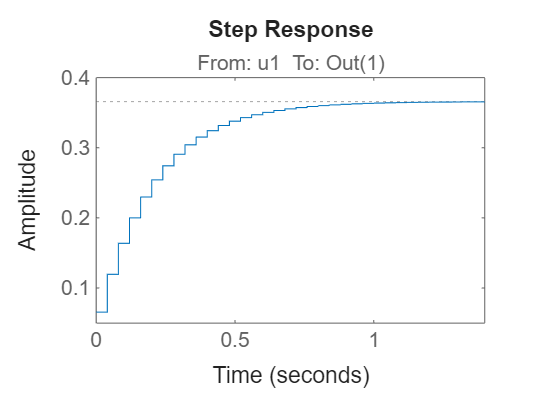

step(89*G) %Vemos la respuesta ante entrada escalón

OBTENCIÓN DE LOS CONTROLADORES PID

figure
%Ajuste manual PID
Kp = 500; Ki = 19000; Kd = 0.0; Ts=0.04;
Cd = pid(Kp, Ki, Kd, 'Ts', Ts)
T = feedback(Cd*G,1);
step(0.386*T)
xlim([0 2]);
grid on

%Hago el controlador con el PID Tuner
%Valores obtenidos con la APP PID Tuner
Kp_tuner = 218.9;
Ki_tuner = 1488;
Kd_tuner = 0;
Ts = 0.04;         

% Crear el controlador discreto
Cd_tuner = pid(Kp_tuner, Ki_tuner, Kd_tuner, 'Ts', Ts)
T_tuner=feedback(Cd_tuner*G,1);
step(1*T_tuner)
grid on

Resultados control PID Tuner

escalonPID_Tuner = [

];


t3 = escalonPID_Tuner(:,1);
refvel3 = escalonPID_Tuner(:,2);
refPWM3 = escalonPID_Tuner(:,3);
vel3    = escalonPID_Tuner(:,4);

figure
plot(t3, vel3, 'r');
xlabel('Tiempo [s]');
ylabel('Velocidad [rad/s]');
title('Evolución de la velocidad con ensayo escalón y PID hallado con PID Tuner');
grid on;

figure;
% Eje izquierdo (referencia velocidad rad/s)
yyaxis left
plot(t3, refvel3, 'b-', 'LineWidth', 1.2); hold on;
ylim([0 0.45]);                 % límites del eje izquierdo
ylabel('Referencia rad/s');

% Eje derecho (velocidad)
yyaxis right
plot(t3, vel3, 'r-', 'LineWidth', 1.2); hold on;
ylim([0 0.45]);                    % límites del eje derecho
ylabel('Velocidad [rad/s]');

xlabel('Tiempo [s]');
title('Referencia y Velocidad Angular Entrada Escalón');
grid on;

legend({'Referencia PWM','Velocidad [m/s]'}, 'Location','best');

Resultados control PID Manual

escalonPID_Manual=[
    ];

t4 = escalonPID_Manual(:,1);
refPWM4 = escalonPID_Manual(:,2);
vel4    = escalonPID_Manual(:,3);

figure
plot(t4, vel4, 'r');
xlabel('Tiempo [s]');
ylabel('Velocidad [rad/s]');
title('Ensayo escalón con PID con ajuste manual');
grid on;

figure;
% Eje izquierdo (referencia velocidad rad/s)
yyaxis left
plot(t4, refPWM4, 'b-', 'LineWidth', 1.2); hold on;
ylim([0 25]);                 % límites del eje izquierdo
ylabel('Referencia rad/s');

% Eje derecho (velocidad)
yyaxis right
plot(t4, vel4, 'r-', 'LineWidth', 1.2); hold on;
ylim([0 24]);                    % límites del eje derecho
ylabel('Velocidad [rad/s]');

xlabel('Tiempo [s]');
title('Referencia y Velocidad Angular Entrada Escalón');
grid on;

legend({'Referencia PWM','Velocidad [rad/s]'}, 'Location','best');




